# getting to the bottom of things


load('C:\Users\eladz\Documents\workProjects\matlab_scripts\IllustrisTNG\matFiles\yangSatSample_Vpoint_m83_sig1_mean_fiber_TNG100.mat')
loadFofSub;
profs8=generate_profile_from_vantagePoint_Catalog(satStructY,fofs,subs,'massThresh',10^8,'mean200')
profs9=generate_profile_from_vantagePoint_Catalog(satStructY,fofs,subs,'massThresh',10^9,'mean200')


## compare average vs. median in the positions

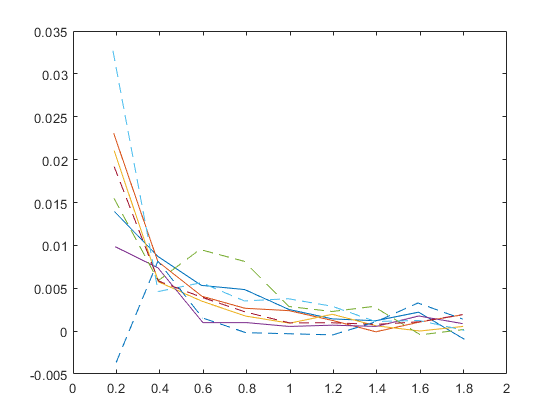

figure
h=[];

plot(profs8.rposMed,profs8.rposAvg./profs8.rposMed-1)
hold on
plot(profs9.rposMed,profs9.rposAvg./profs9.rposMed-1,'--')

Differences in the median vs. average position within the distance bins are of order 1% in the inner bin and less the 0.5% in the outer bins. 

## compare stellar mass profiles with different threshold

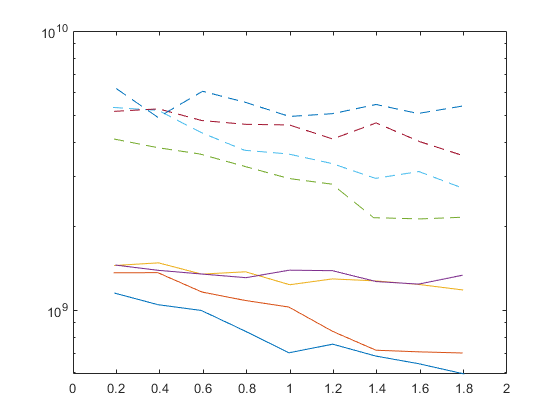

figure
h=[];

semilogy(profs8.rposMed(:,:),squeeze(profs8.smassMedMed(3,:,:)))
hold on
semilogy(profs9.rposMed(:,:),squeeze(profs9.smassMedMed(3,:,:)),'--')

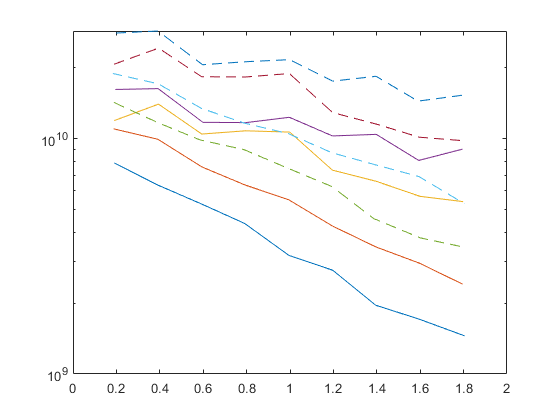


figure
h=[];

semilogy(profs8.rposMed(:,:),squeeze(profs8.smassAvgMed(3,:,:)))
hold on
semilogy(profs9.rposMed(:,:),squeeze(profs9.smassAvgMed(3,:,:)),'--')

## Plot scatter

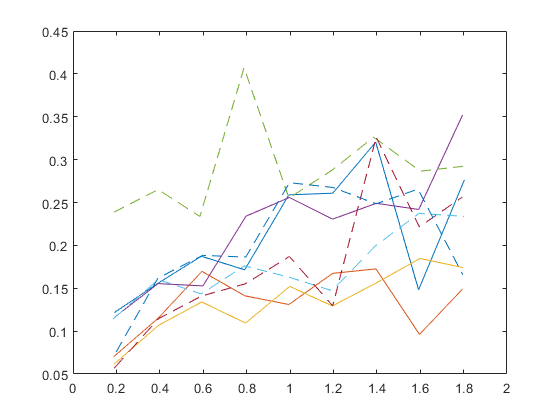

figure
plot(profs8.rposMed(:,:),...
    squeeze(profs8.smassMedMed(4,:,:)-profs8.smassMedMed(2,:,:))./squeeze(profs8.smassMedMed(3,:,:)));
hold on
plot(profs9.rposMed(:,:),...
    squeeze(profs9.smassMedMed(4,:,:)-profs9.smassMedMed(2,:,:))./squeeze(profs9.smassMedMed(3,:,:)),'--');

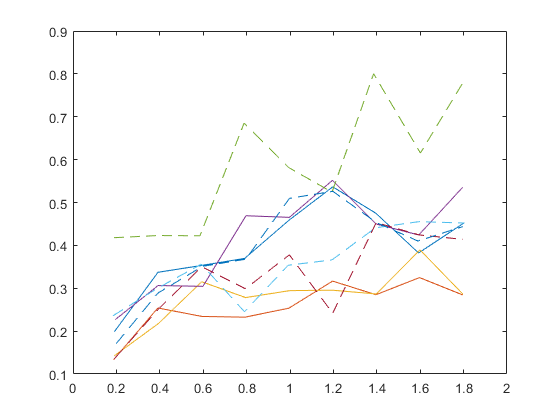


figure
plot(profs8.rposMed(:,:),...
    squeeze(profs8.smassMedMed(5,:,:)-profs8.smassMedMed(1,:,:))./squeeze(profs8.smassMedMed(3,:,:)));
hold on
plot(profs9.rposMed(:,:),...
    squeeze(profs9.smassMedMed(5,:,:)-profs9.smassMedMed(1,:,:))./squeeze(profs9.smassMedMed(3,:,:)),'--');